# CHW05 - Tensor Decompositions - 401110448 - Mohammad Sadra Hosseini

#### Note: in part 3, unfortunately after i put them in subplot and add title and sgtitle, pictures are very small. my discussions in this report is for before use them on final results.

## Q1.

in this part, first i use hosvd algorithm for initializing factor matrices. i use below structure for hooi algorithm


$$\mathcal{Y} \leftarrow \mathcal{X} \times_1 U_1^T ... \times_{n-1}U_{n-1}^T\times_{n+1}U_{n+1}^T...\times_N U_N^T$$



$$U_n \leftarrow R_nleading left singular vectors of \mathbf{Y_n}$$


and this algorithm will repeat for a maximum size of iterations for convergence. after that we can calculate core tensor using this fact that our factor matrices are orthogonal, so we can multiply our initial tensor by transpose(inverse) of our factor matrices.


$$\mathcal{G} \leftarrow \mathcal{X} \times_1 U_1^T \times_2 U_2^T ... \times_N U_N^T$$


## Q2.

clc, clear, close all;

first load images on a tensor called "images".

images = zeros(112,92,50);
for i = 1 : 5
    for j = 1 : 10
        images(:, :, (i - 1) * 10 + j) = imread(['ORL\s', num2str(i), '\', num2str(j), '.pgm']);
    end
end

now for get better results and also for unify the input of all algorithms, first i use hosvd, same that i wrote in hooi function

R = [5, 5, 5];
% using hosvd for initializing factor matrices
ten1 = tenmat(images, 1);
[U, ~, ~] = svd(ten1.data);
U1 = U(:, 1 : R(1));

ten2 = tenmat(images, 2);
[U, ~, ~] = svd(ten2.data);
U2 = U(:, 1 : R(2));

ten3 = tenmat(images, 3);
[U, ~, ~] = svd(ten3.data);
U3 = U(:, 1 : R(3));

now decompose using my hooi function and plot U3 columns.

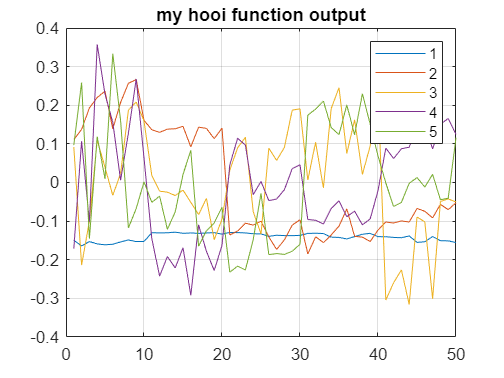

[~, ~, ~, my_hooi_U3] = my_hooi(tensor(double(images)), R);

figure;
for i = 1 : 5  
    plot(my_hooi_U3(:, i));
    hold on
end
legend('1', '2', '3', '4', '5');
grid on; 
title('my hooi function output');

tucker als decomposition and plot U3.

T = tucker_als(tensor(double(images)), R);


Tucker Alternating Least-Squares:
 Iter  1: fit = 7.725278e-01 fitdelta = 7.7e-01
 Iter  2: fit = 8.043671e-01 fitdelta = 3.2e-02
 Iter  3: fit = 8.052735e-01 fitdelta = 9.1e-04
 Iter  4: fit = 8.053181e-01 fitdelta = 4.5e-05


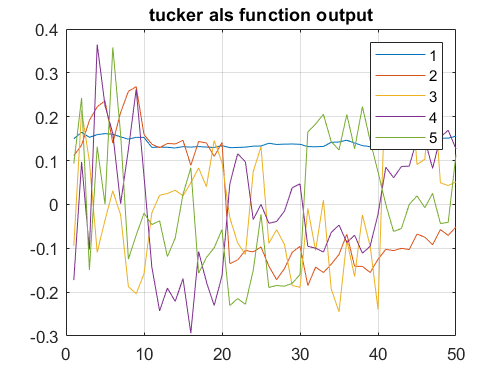


figure;
tucker_als_U3 = T.u{3};
for i = 1 : 5  
    plot(tucker_als_U3(:, i));
    hold on
end
legend('1', '2', '3', '4', '5');
grid on; 
title('tucker als function output');

NNTD(non negative tensor decomposition) and plot U3.

opts.maxit = 1000;
opts.tol = 1e-4;
[A, C, Out] = NNTD(tensor(images), R, opts);

Iteration:  184


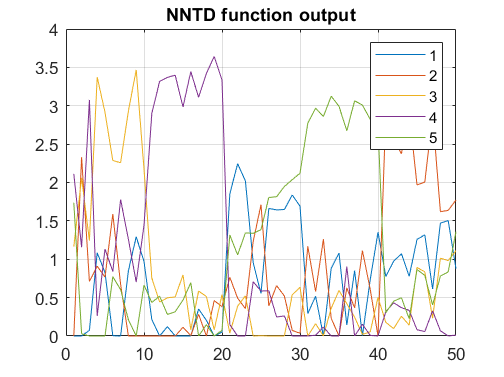


figure;
nntd_U3 = A{3};
for i = 1 : 5
    plot(nntd_U3(:, i));
    hold on
end
legend('1', '2', '3', '4', '5');
grid on; 
title('NNTD function output');

as we can see from graphs, NNTD algorithm can cluster better than other algorithms(almost horizental axis divided into 5 section and in each section one of clusters has more amplitude than others). in my opinion, this happens because our data are originaly non negative, so a non negative algorithm must works better here. als and hooi algorithm doesn't cluster properly, particularly one of clusters (blue one) is almost disable.

## Q3.

3.1

clc, clear, close all;

first loading data and also down with rate 4 that means we keep only one pixel from every 4 pixels

down_sample_rate = 4;
images = zeros(10, 9, 192 * 168 / (down_sample_rate ^ 2));
image_index_string = {'+000', '+010', '-010', '+025', '-025', '+050', '-050', '+070', '-070'};
folder_index_string = {'01', '02', '03', '04', '05', '06', '07', '08', '09', '10'};
for i = 1 : length(folder_index_string)
    for j = 1 : length(image_index_string)
        image = imread(append('Illumination_Yale\yaleB', string(folder_index_string(i)), '\yaleB', string(folder_index_string(i)), '_P00A', string(image_index_string(j)), 'E+00.pgm'));
        down_sampled_image = image(1 : down_sample_rate : end, 1 : down_sample_rate : end);
        images(i, j, :) = down_sampled_image(:);
    end
end

now apply tucker als function on this tensor with different ranks as [10, 1, 90], [10, 3, 90]  and [10, 5, 90]

illumination1 = tucker_als(tensor(double(images)),[10 1 90]);


Tucker Alternating Least-Squares:
 Iter  1: fit = 5.628250e-01 fitdelta = 5.6e-01
 Iter  2: fit = 5.632942e-01 fitdelta = 4.7e-04
 Iter  3: fit = 5.633038e-01 fitdelta = 9.6e-06


illumination3 = tucker_als(tensor(double(images)),[10 3 90]);


Tucker Alternating Least-Squares:
 Iter  1: fit = 6.062682e-01 fitdelta = 6.1e-01
 Iter  2: fit = 9.032596e-01 fitdelta = 3.0e-01
 Iter  3: fit = 9.033897e-01 fitdelta = 1.3e-04
 Iter  4: fit = 9.033898e-01 fitdelta = 1.3e-07


illumination5 = tucker_als(tensor(double(images)),[10 5 90]);


Tucker Alternating Least-Squares:
 Iter  1: fit = 8.877880e-01 fitdelta = 8.9e-01
 Iter  2: fit = 9.334835e-01 fitdelta = 4.6e-02
 Iter  3: fit = 9.340692e-01 fitdelta = 5.9e-04
 Iter  4: fit = 9.344187e-01 fitdelta = 3.5e-04
 Iter  5: fit = 9.346381e-01 fitdelta = 2.2e-04
 Iter  6: fit = 9.347716e-01 fitdelta = 1.3e-04
 Iter  7: fit = 9.348505e-01 fitdelta = 7.9e-05


now for reconstruct images, i use below equations


$$images \approx core \times_1 U_1 \times_2U_2\times_3U_3 = reconstructed$$


reconstructed1 = ttm(illumination1.core,{illumination1.u{1},illumination1.u{2},illumination1.u{3}},[1 2 3]);
reconstructed3 = ttm(illumination3.core,{illumination3.u{1},illumination3.u{2},illumination3.u{3}},[1 2 3]);
reconstructed5 = ttm(illumination5.core,{illumination5.u{1},illumination5.u{2},illumination5.u{3}},[1 2 3]);

now plot reconstructed images 

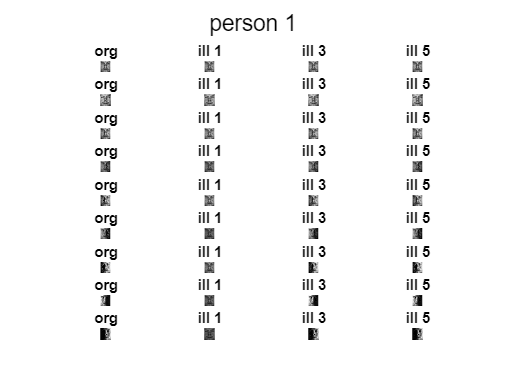

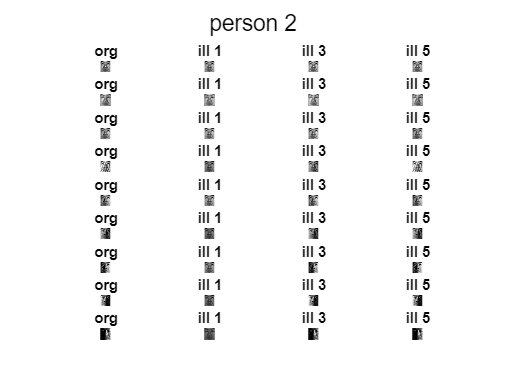

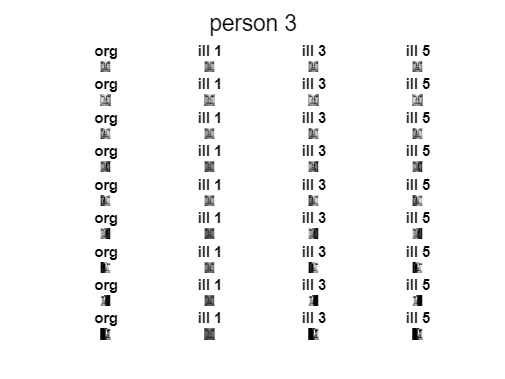

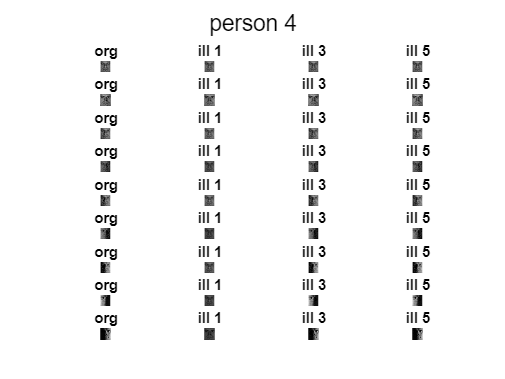

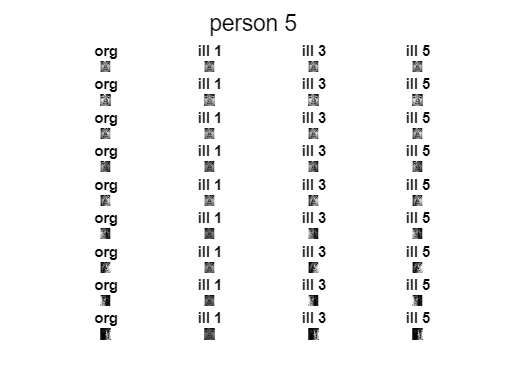

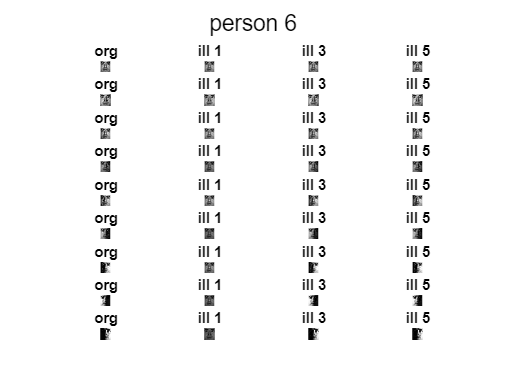

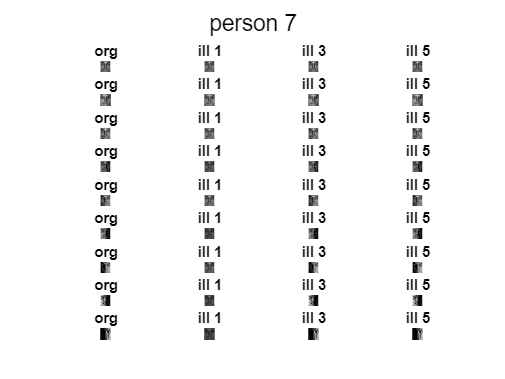

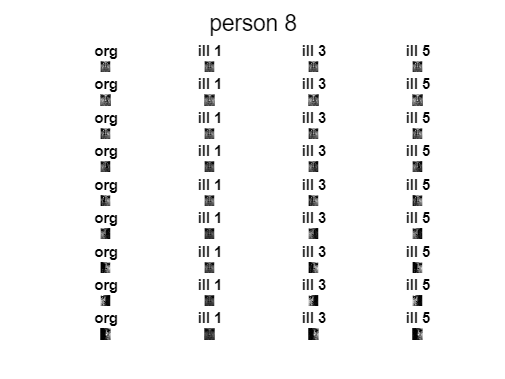

for i = 1 : 10
    figure;
    for j = 1 : 9
        original_image = reshape(double(images(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 1);
        imshow(uint8(original_image));
        title('org');
        
        ill_image1 = reshape(double(reconstructed1(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 2);
        imshow(uint8(ill_image1));
        title('ill 1');

        ill_image3 = reshape(double(reconstructed3(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 3);
        imshow(uint8(ill_image3));
        title('ill 3');

        ill_image5 = reshape(double(reconstructed5(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 4);
        imshow(uint8(ill_image5));
        title('ill 5');
    end
    sgtitle(append('person ', num2str(i)));
end

as we can see in the graphs above, if we use tucker decomposition, in less illuminations, this decomposition filters more shadows from original picture.

3.2

first convert images to matrix form by convert it to mode-3 unfolding. then apply svd and keep first k singular vectors and values. for reconstructing multiple these k components together as usual. then reshape reconstructed forms to image form for display them. after that plot them.

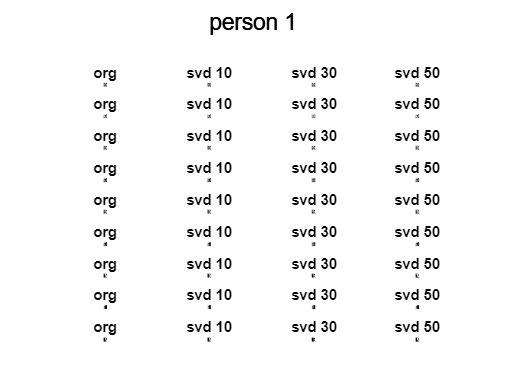

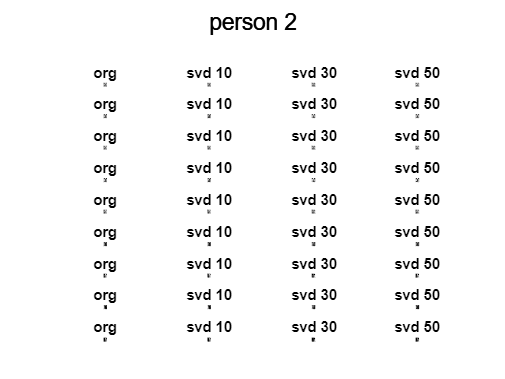

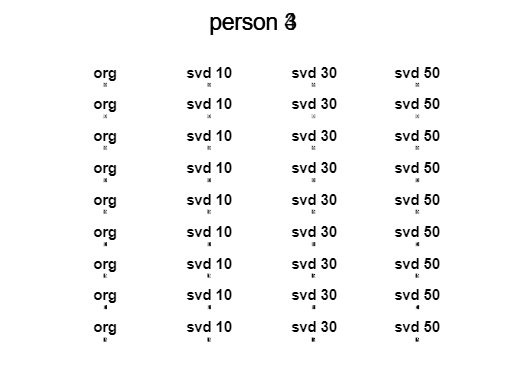

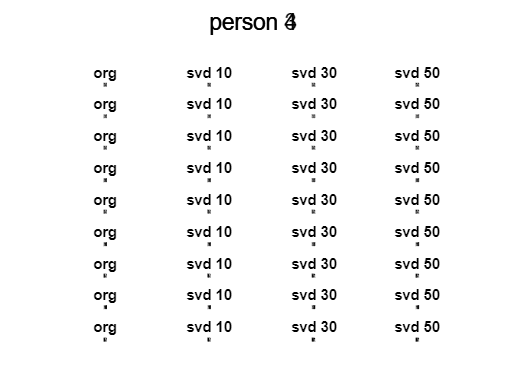

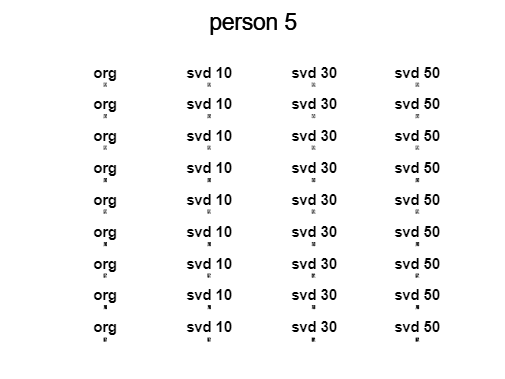

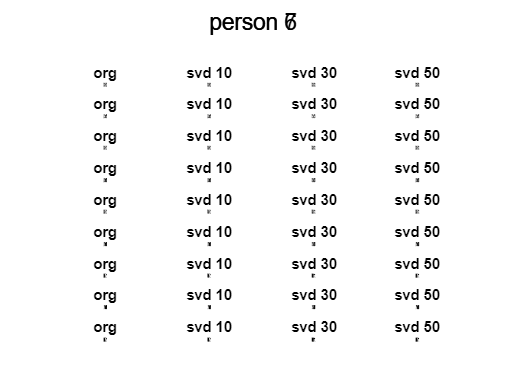

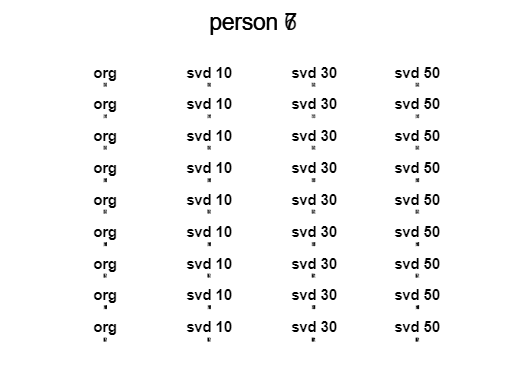

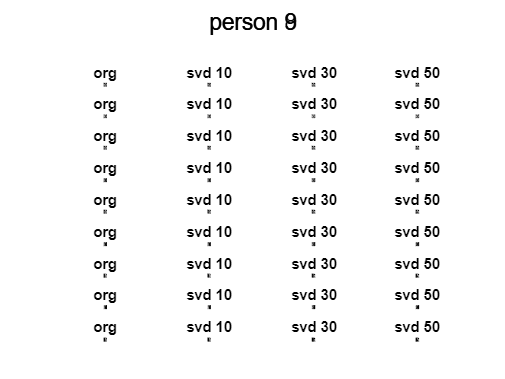

matricized_images = tenmat(images, 3);

[U, S, V] = svd(double(matricized_images));

reconstructed_svd10 = U(:, 1 : 10) * S(1 : 10, 1 : 10) * V(:, 1 : 10)';
reconstructed_svd30 = U(:, 1 : 30) * S(1 : 30, 1 : 30) * V(:, 1 : 30)';
reconstructed_svd50 = U(:, 1 : 50) * S(1 : 50, 1 : 50) * V(:, 1 : 50)';

mat_svd10 = reshape(transpose(reconstructed_svd10), [10, 9, 192 * 168 / (down_sample_rate ^ 2)]);
mat_svd30 = reshape(transpose(reconstructed_svd30), [10, 9, 192 * 168 / (down_sample_rate ^ 2)]);
mat_svd50 = reshape(transpose(reconstructed_svd50), [10, 9, 192 * 168 / (down_sample_rate ^ 2)]);


for i = 1 : 10
    figure;
    for j = 1 : 9
        original_image = reshape(double(mat_svd10(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 1);
        imshow(uint8(original_image));
        title('org');
        
        ill_image1 = reshape(double(mat_svd10(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 2);
        imshow(uint8(ill_image1));
        title('svd 10');

        ill_image3 = reshape(double(mat_svd10(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 3);
        imshow(uint8(ill_image3));
        title('svd 30');

        ill_image5 = reshape(double(reconstructed5(i, j, :)), 192 / down_sample_rate, 168 / down_sample_rate);
        subplot(9, 4, (j - 1) * 4 + 4);
        imshow(uint8(ill_image5));
        title('svd 50');
    end
    sgtitle(append('person ', num2str(i)));
end

in lower ranks, quality of all pictures decrease monotonically. so svd can not delete shadows like tucker decomposition. in higher ranks, as expectation, result may gets close to original picture.

3.3

tucker decompostion delete shadows and extra noise on picture that come from shadow, but svd delete informations of picture monotonically from all of it and at last, the results of tucker are so better than svd(in some of pictures, tucker works great and get pictures with higher quailty after deleting shadows, but svd works bad here).